close all;
clear all;

## Transition Frequency

% 171 %
blue(1).one = [1153 1153];   % F=1/2相对频率(MHz)
blue(1).three = [835 835];   % F=3/2相对频率(MHz)
blue(1).slower = [blue(1).three(1)-40-780 blue(1).three(1)-40-780];   % 171 Zeeman Slower
blue(1).MOT = [blue(1).three(1)-40 blue(1).three(1)-40];   % 171 blue MOT

green(1).one = [-5936 -5936];   % F=1/2 (MHz)
green(1).three = [0 0];   % F=3/2

% 173 %
blue(2).seven = [589 589];   % F=7/2相对频率(MHz)
blue(2).three = [515 515];   % F=3/2相对频率(MHz)
blue(2).five = [-250 -250];   % F=5/2相对频率(MHz)
blue(2).slower = [blue(2).seven(1)-40-780 blue(2).seven(1)-40-780];   % 173 Zeeman Slower
blue(2).MOT = [blue(2).seven(1)-40 blue(2).seven(1)-40];   % 173 blue MOT

green(2).seven = [-6191 -6191];   % F=7/2 (MHz)
green(2).five = [-1493 -1493];   % F=5/2
green(2).three = [2 2];   % F=3/2
green(2).Rot1minus = [green(2).seven(1)+5392.7 green(2).seven(1)+5392.7];  % sigma-sigma^2
green(2).Rot2minus = [green(2).seven(1)+5233.5 green(2).seven(1)+5233.5];  % sigma-2*sigma^2
%green(2).Rot1plus = [green(2).seven(1)+4698 green(2).seven(1)+4698];  % sigma+sigma^2
%green(2).Rot2plus = [green(2).seven(1)+4887 green(2).seven(1)+4887];  % sigma+2*sigma^2


## 399-nm Laser

close all;
f1 = figure(1);

% 171 HFS %
x1 = [20,50];

line(1).HFS = plot(x1,blue(1).one , x1,blue(1).three);
set(line(1).HFS,'color','black','linewidth',3);
hold on;

line(1).slower = plot(x1,blue(1).slower,linestyle = '--');
set(line(1).slower,'color',[0.2118 0.5647 0.7529],'linewidth',2.5);

line(1).MOT = plot(x1,blue(1).MOT,linestyle = '--');
set(line(1).MOT,'color',[0.0118 0.3059 0.4824],'linewidth',2.5);


% 173 HFS %
x2 = [70,100];

line(2).HFS = plot(x2,blue(2).seven , x2,blue(2).three , x2,blue(2).five);
set(line(2).HFS,'color','black','linewidth',3);

line(2).slower = plot(x2,blue(2).slower,linestyle = '--');
set(line(2).slower,'color',[0.4549 0.6627 0.8118],'linewidth',2.5);

line(2).MOT = plot(x2,blue(2).MOT,linestyle = '--');
set(line(2).MOT,'color',[0.0196 0.4392 0.6902],'linewidth',2.5);


set(gca,'FontWeight','normal','FontSize',20,'FontName','arial','FontAngle','italic');
xlim([0 120]);
xticks([]);
%xticks([35 85]);
%xticklabels({'171','173'});
ylim([blue(2).five(1)-100 , blue(1).one(1)+100]);
yticks([blue(2).five(1) , blue(2).three(1) , blue(2).seven(1) , blue(1).three(1) , blue(1).one(1)]);
ylabel('Relative Frequency (MHz)','FontSize',24,...
    'FontWeight','bold','FontName','arial','FontAngle','normal');
title('399-nm Laser','FontName','times','FontWeight','bold',...
    'FontSize',35,'FontAngle','normal');


### Note

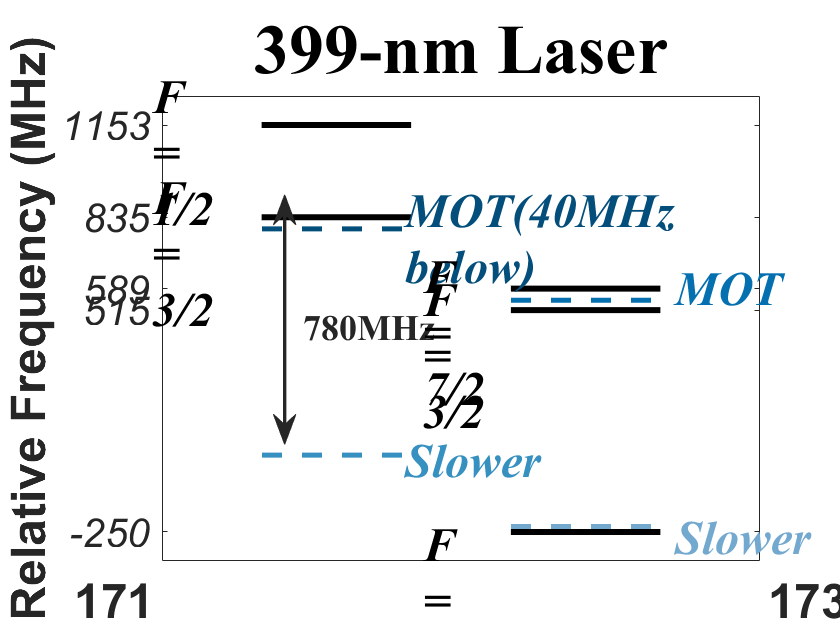

xlabel({'171                                              173'},...
    'FontWeight','bold','FontSize',24,...
    'FontName','Arial','FontAngle','normal');

% 171 energy level %
annotation(f1,'textbox',[0.1695 0.8459 0.0919 0.0542],...
    'String',{'F = 1/2'},'LineStyle','none',...
    'FontWeight','bold', 'FontSize',24,...
    'FontName','Times New Roman','FontAngle','italic');

annotation(f1,'textbox',[0.1695 0.6850 0.0919 0.0542],...
    'String',{'F = 3/2'},'LineStyle','none',...
    'FontWeight','bold','FontSize',24,...
    'FontName','Times New Roman','FontAngle','italic');

% 173 energy level %
annotation(f1,'textbox',[0.4922 0.5597 0.0919 0.0542],...
    'String',{'F = 7/2'},'LineStyle','none',...
    'FontWeight','bold','FontSize',24,...
    'FontName','Times New Roman','FontAngle','italic');

annotation(f1,'textbox',[0.4922 0.5228 0.0919 0.0542],...
    'String',{'F = 3/2'},'LineStyle','none',...
    'FontWeight','bold','FontSize',24,...
    'FontName','Times New Roman','FontAngle','italic');

annotation(f1,'textbox',[0.4922 0.1344 0.0919 0.0542],...
    'String',{'F = 5/2'},'LineStyle','none',...
    'FontWeight','bold','FontSize',24,...
    'FontName','Times New Roman','FontAngle','italic');

% 171 cooling %
annotation(f1,'textbox',[0.4704 0.6651 0.0743*3.5 0.0542],...
    'Color',[0.0118 0.3059 0.4824],'String',{'MOT(40MHz below)'},...
    'LineStyle','none','FontWeight','bold',...
    'FontSize',24,'FontName','Times New Roman',...
    'FontAngle','italic');

annotation(f1,'textbox',[0.4704 0.2687 0.0882 0.0542],...
    'Color',[0.2118 0.5647 0.7529],'String',{'Slower'},...
    'LineStyle','none','FontWeight','bold',...
    'FontSize',24,'FontName','Times New Roman',...
    'FontAngle','italic');

% 173 cooling %
annotation(f1,'textbox',[0.7917 0.5409 0.0743 0.0542],...
    'Color',[0.0196 0.4392 0.6902],'String',{'MOT'},...
    'LineStyle','none','FontWeight','bold',...
    'FontSize',24,'FontName','Times New Roman',...
    'FontAngle','italic');

annotation(f1,'textbox',[0.7917 0.1454 0.0882 0.0542],...
    'Color',[0.4549 0.6627 0.8118],'String',{'Slower'},...
    'LineStyle','none','FontWeight','bold',...
    'FontSize',24,'FontName','Times New Roman',...
    'FontAngle','italic');

% frequency between slower & MOT %
annotation(f1,'doublearrow',[0.3389 0.3389],[0.6908 0.2948],...
    'Color',[0.1490 0.1490 0.1490],'LineWidth',1.7,...
    'Head2Width',15,'Head2Length',15,...
    'Head1Width',15,'Head1Length',15);

annotation(f1,'textbox',[0.3491 0.4780 0.0819 0.0440],...
    'Color',[0.1490 0.1490 0.1490],'String',{'780MHz'},...
    'LineStyle','none','FontWeight','bold',...
    'FontSize',18,'FontName','Times New Roman');

## 556-nm Laser

close all;
f2 = figure(2);

% 171 HFS %
x1 = [20 50];

line(3).HFS = plot(x1,green(1).one , x1,green(1).three);
set(line(3).HFS,'color','black','linewidth',3);
hold on;


% 173 HFS %
x2 = [70,100];

line(4).HFS = plot(x2,green(2).seven , x2,green(2).three , x2,green(2).five);
set(line(4).HFS,'color','black','linewidth',3);

%line(4).Rot1plus = plot(x2,green(2).Rot1plus,linestyle = '--');
%set(line(4).Rot1plus,'color',[0.5961 0.9843 0.5961],'linewidth',2.5);
%line(4).Rot2plus = plot(x2,green(2).Rot2plus,linestyle = '--');
%set(line(4).Rot2plus,'color',[0.2353 0.7020 0.4431],'linewidth',2.5);
line(4).Rot2minus = plot(x2,green(2).Rot2minus,linestyle = '--');
set(line(4).Rot2minus,'color',[0.1961 0.8039 0.1961],'linewidth',2.5);
line(4).Rot1minus = plot(x2,green(2).Rot1minus,linestyle = '--');
set(line(4).Rot1minus,'color',[0.1333 0.5451 0.1333],'linewidth',2.5);

set(gca,'FontWeight','normal','FontSize',20,'FontName','arial','FontAngle','italic');
xlim([0 120]);
xticks([]);
ylim([green(2).seven(1)-500 , green(2).three(1)+500]);
yticks([green(2).seven(1) , green(1).one(1) , green(2).five(1) , green(2).Rot1minus(1) , green(1).three(1)]);
ylabel('Relative Frequency (MHz)','FontSize',24,...
    'FontWeight','bold','FontName','arial','FontAngle','normal');
title('556-nm Laser','FontName','times','FontWeight','bold',...
    'FontSize',35,'FontAngle','normal');


### Note

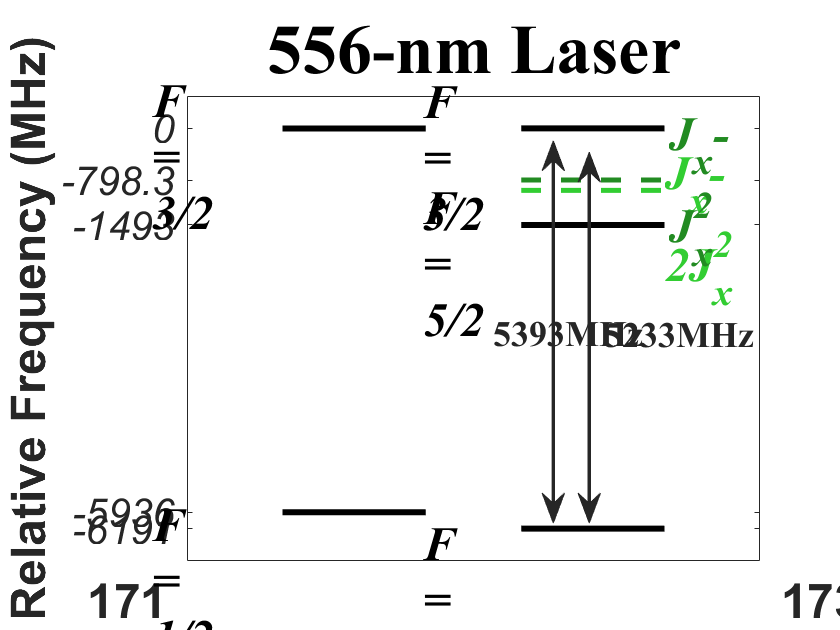

xlabel({'171                                              173'},...
    'FontWeight','bold','FontSize',24,...
    'FontName','Arial','FontAngle','normal');

% 171 energy level %
annotation(f2,'textbox',[0.1695 0.8388 0.0919 0.0542],...
    'String',{'F = 3/2'},'LineStyle','none',...
    'FontWeight','bold', 'FontSize',24,...
    'FontName','Times New Roman','FontAngle','italic');

annotation(f2,'textbox',[0.1695 0.1667 0.0919 0.0542],...
    'String',{'F = 1/2'},'LineStyle','none',...
    'FontWeight','bold','FontSize',24,...
    'FontName','Times New Roman','FontAngle','italic');

% 173 energy level %
annotation(f2,'textbox',[0.4922 0.8380 0.0919 0.0542],...
    'String',{'F = 3/2'},'LineStyle','none',...
    'FontWeight','bold','FontSize',24,...
    'FontName','Times New Roman','FontAngle','italic');

annotation(f2,'textbox',[0.4922 0.6690 0.0919 0.0542],...
    'String',{'F = 5/2'},'LineStyle','none',...
    'FontWeight','bold','FontSize',24,...
    'FontName','Times New Roman','FontAngle','italic');

annotation(f2,'textbox',[0.4922 0.1368 0.0919 0.0542],...
    'String',{'F = 7/2'},'LineStyle','none',...
    'FontWeight','bold','FontSize',24,...
    'FontName','Times New Roman','FontAngle','italic');

% sigma-sigma^2 %
annotation(f2,'textbox',[0.7850 0.7760 0.1500 0.0650],...
    'Color',[0.1333 0.5451 0.1333],'String',{'J_x- J_x^2'},...
    'LineStyle','none','FontWeight','bold',...
    'FontSize',24,'FontName','Times New Roman',...
    'FontAngle','italic');

% sigma-2*sigma^2 %
annotation(f2,'textbox',[0.7800 0.7140 0.1535 0.0650],...
    'Color',[0.1961 0.8039 0.1961],'String',{'J_x- 2J_x^2'},...
    'LineStyle','none','FontWeight','bold',...
    'FontSize',24,'FontName','Times New Roman',...
    'FontAngle','italic');

% frequency between cooling & rotation %
annotation(f2,'doublearrow',[0.6587 0.6587],[0.7765 0.1698],...
    'Color',[0.1490 0.1490 0.1490],'LineWidth',1.7,...
    'Head2Width',15,'Head2Length',15,...
    'Head1Width',15,'Head1Length',15);

annotation(f2,'textbox',[0.5750 0.4680 0.0900 0.0440],...
    'Color',[0.1490 0.1490 0.1490],'String',{'5393MHz'},...
    'LineStyle','none','FontWeight','bold',...
    'FontSize',18,'FontName','Times New Roman');

annotation(f2,'doublearrow',[0.7015 0.7015],[0.7584 0.1698],...
    'Color',[0.1490 0.1490 0.1490],'LineWidth',1.7,...
    'Head2Width',15,'Head2Length',15,...
    'Head1Width',15,'Head1Length',15);

annotation(f2,'textbox',[0.7075 0.4670 0.0900 0.0440],...
    'Color',[0.1490 0.1490 0.1490],'String',{'5233MHz'},...
    'LineStyle','none','FontWeight','bold',...
    'FontSize',18,'FontName','Times New Roman');